Settings

Alles löschen

clear
clc

LaTex-Interpreter als Standard für Grafiken setzen

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Schriftgröße für Grafiken setzen

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Verzeichnis wechseln (in Verzeichnis des Live-Skripts)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

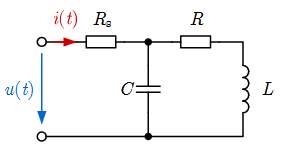

Erstellen symbolische Variablen

syms('R', 'positive')
syms('L', 'positive')
syms('C', 'positive')
syms('R_s', 'positive')
syms('t')
syms('s')

Numerische Werte

R_num = 8.2;
R_s_num = 108;
L_num = 660e-6;
C_num = 49e-9;
U_0 = 10

U_0 =     10.0000e+000

## Bestimmung von i(t) mithilfe der laplace Transformation

Berechnung der Impedanz

Z_ers = R_s + (1 /((s * C) + 1/(R + s * L)))

$$Z\_ers = R_{s}+\frac{1}{C\,s+\frac{1}{R+L\,s}}$$

U_e = U_0 *heaviside(t)

$$U\_e = 10\,\mathrm{heaviside}\left(t\right)$$

U_s = laplace(U_e);
I_s = U_s / Z_ers

$$I\_s = \frac{10}{s\,\left(R_{s}+\frac{1}{C\,s+\frac{1}{R+L\,s}}\right)}$$

inverse Laplace-Transformation um i(t) zu erhalten 

i_t = ilaplace(I_s, s, t)

$$i\_t = \begin{array}{l} \frac{10}{R+R_{s}}+\frac{10\,R\,{\mathrm{e}}^{-\frac{t\,\left(L+C\,R\,R_{s}\right)}{2\,C\,L\,R_{s}}}\,\left(\cosh\left(\sigma_{1}\right)-\frac{C\,L\,R_{s}\,\sinh\left(\sigma_{1}\right)\,\left(\frac{L+C\,R\,R_{s}}{2\,C\,L\,R_{s}}+\frac{10\,L-10\,C\,R^{2}}{10\,C\,L\,R}\right)}{\sigma_{2}}\right)}{R_{s}\,\left(R+R_{s}\right)}\\ \mathrm{where}\\ \sigma_{1}=\frac{t\,\sigma_{2}}{C\,L\,R_{s}}\\ \sigma_{2}=\sqrt{\frac{C^{2}\,R^{2}\,{R_{s}}^{2}}{4}-\frac{C\,L\,R\,R_{s}}{2}-C\,L\,{R_{s}}^{2}+\frac{L^{2}}{4}} \end{array}$$

subs(i_t, 'exp') 

$$ans = \begin{array}{l} \frac{10}{R+R_{s}}+\frac{10\,R\,{\mathrm{e}}^{-\frac{\text{exp}\,\left(L+C\,R\,R_{s}\right)}{2\,C\,L\,R_{s}}}\,\left(\cosh\left(\sigma_{1}\right)-\frac{C\,L\,R_{s}\,\sinh\left(\sigma_{1}\right)\,\left(\frac{L+C\,R\,R_{s}}{2\,C\,L\,R_{s}}+\frac{10\,L-10\,C\,R^{2}}{10\,C\,L\,R}\right)}{\sigma_{2}}\right)}{R_{s}\,\left(R+R_{s}\right)}\\ \mathrm{where}\\ \sigma_{1}=\frac{\text{exp}\,\sigma_{2}}{C\,L\,R_{s}}\\ \sigma_{2}=\sqrt{\frac{C^{2}\,R^{2}\,{R_{s}}^{2}}{4}-\frac{C\,L\,R\,R_{s}}{2}-C\,L\,{R_{s}}^{2}+\frac{L^{2}}{4}} \end{array}$$

## Grafische Darstellung 

um i(t) darzustellen müssen symbolische Variable ndurch numerische ersetzt werden, zudem werden die Wert für den plot berechnet 

i_t_num = subs(i_t, [R, L, C, R_s], [R_num, L_num, C_num, R_s_num]);

t_plot = linspace(-1e-5, 1e-4, 1001);
i_t_num_plot = double(subs(i_t_num, t , t_plot));


figure
plot(t_plot, i_t_num_plot, 'LineWidth', 1.5); % Corrected argument order
grid on;
xlabel('Zeit in s');
ylabel('Strom in A');
xlim([-1e-5, 1e-4])
ylim([-1e-2, 1e-1])

## Bestimmung Kenngrößen

Zeitkonstante

Frequenzen von Schwingungen